# Thermoeconomic Analysis Demo

Use ThermoeconomicAnalysis function to compute the exergy cost of a plant

#### Select and check the model file

filename="C:\Users\ctorr\Documents\Proyectos\TaesLab\Examples\gturbo\gturbo_model.json";
data=ReadDataModel(filename);

#### Select the parameters

States=convertCharsToStrings(data.States);
State=convertStringsToChars(States(3));
CostTables=cType.DEFAULT_COST_TABLES;
if data.isResourceCost
    Samples=convertCharsToStrings(data.ResourceSamples);
    ResourceSample=convertStringsToChars(Samples(1));
    CostTables='ALL';
end

#### Compute Cost Analysis

res=ThermoeconomicAnalysis(data,'State',State, ...
    'CostTables',CostTables,'ResourceSample',ResourceSample,'Show',true);

Process Exergy Cost

Key        P*(kW)    Pe*(kW)    Pr*(kW)     F*(kW)     R*(kW)
——————————————————————————————————————————————————————————————
CMB1     15074.90   14358.00     716.90   14358.00     716.90
CMB2     11360.68   10810.00     550.68   10810.00     550.68
CMP1      8438.14    7446.52     991.61    8099.47     338.66
CMP2     10374.97    9427.35     947.61   10253.99     120.97
TRB1     20289.16   18583.12    1706.04   20159.85     129.31
TRB2     17519.82   16177.83    1341.99   17402.16     117.66
PHTR     19478.61   17899.38    1579.23   19254.00     224.61
GEN      19455.51   17887.08    1568.43   19455.51       0.00
COOL      1564.07    1380.27     183.80    1564.07       0.00
STCK      6347.21    5900.65     446.56    6347.21       0.00


Process Unit Exergy Cost

Key      kP*(J/J)  kPe*(J/J)  kPr*(J/J)   kF*(J/J)   kR*(J/J)     k(J/J)
—————————————————————————————————————————————————————————————————————————
CMB1       1.4341     1.3659     0.0682     1.0000     0.06

#### Show Results

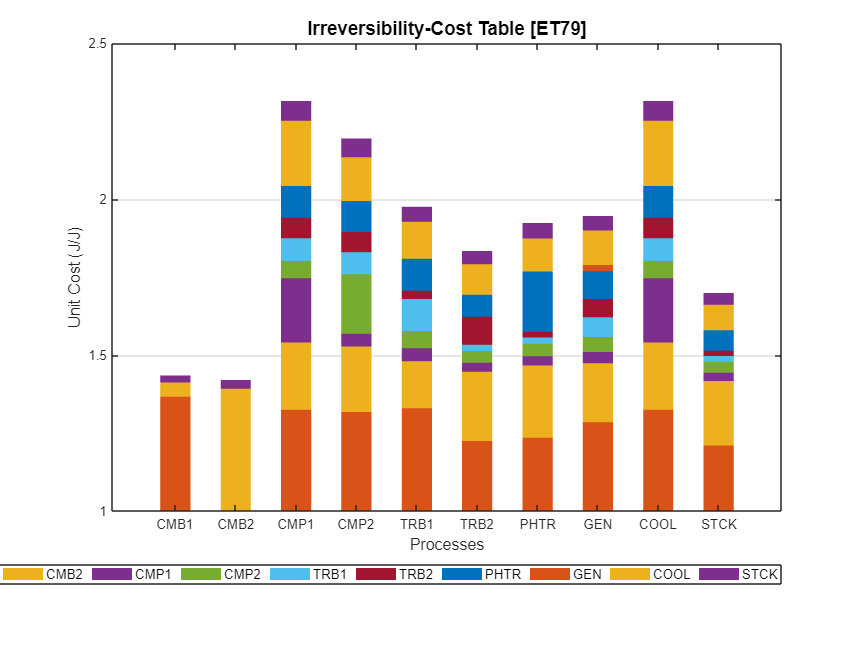

showGraph(res);